x=linspace(-2,2,15)

x =    -2.0000   -1.7143   -1.4286   -1.1429   -0.8571   -0.5714   -0.2857         0    0.2857    0.5714    0.8571    1.1429    1.4286    1.7143    2.0000


f= exp(sin(5.5*x))

f =     2.7183    1.0038    0.3679    0.9975    2.7183    1.0013    0.3679    1.0000    2.7183    0.9987    0.3679    1.0025    2.7183    0.9962    0.3679


u=linspace(-2,2,100)

u =    -2.0000   -1.9596   -1.9192   -1.8788   -1.8384   -1.7980   -1.7576   -1.7172   -1.6768   -1.6364   -1.5960   -1.5556   -1.5152   -1.4747   -1.4343   -1.3939   -1.3535   -1.3131   -1.2727   -1.2323   -1.1919   -1.1515   -1.1111   -1.0707   -1.0303   -0.9899   -0.9495   -0.9091   -0.8687   -0.8283   -0.7879   -0.7475   -0.7071   -0.6667   -0.6263   -0.5859   -0.5455   -0.5051   -0.4646   -0.4242   -0.3838   -0.3434   -0.3030   -0.2626   -0.2222   -0.1818   -0.1414   -0.1010   -0.0606   -0.0202


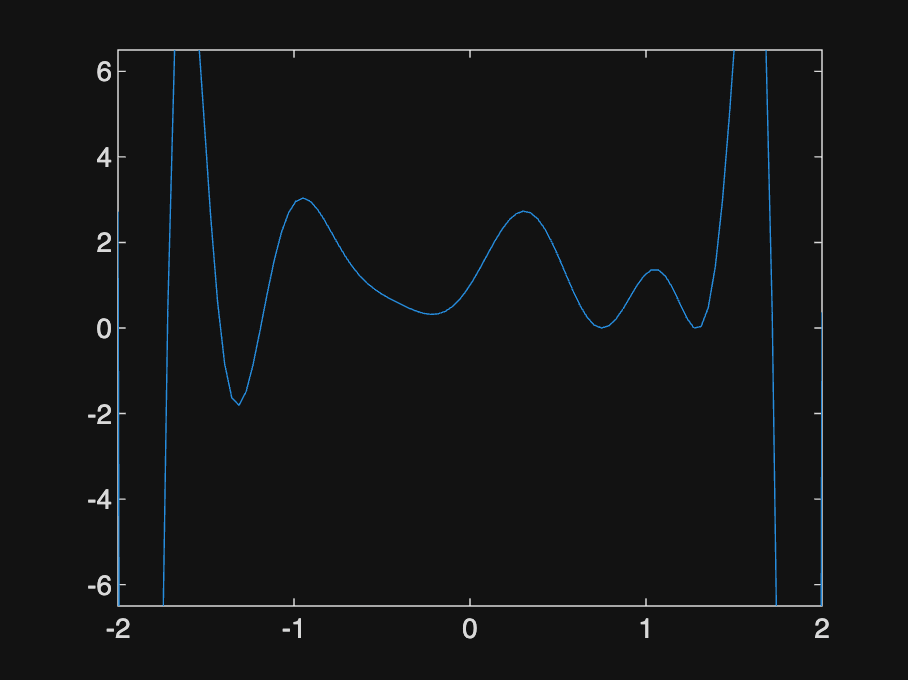

v=lagrange_polyinterp(x,f,u);

plot(u,v)
ylim([-6.5,6.5])

function v = lagrange_polyinterp(x,f,u)
    n=length(x);
    m=length(u);
    v=zeros(m,1);
    
    for k=1:m
        p=0;
        for j=1:n
            prod=1;
            
            for i=1:n
                if i~=j
                    prod=prod* ((u(k)-x(i)) / (x(j)-x(i)));
                end
            end
            p=p+prod*f(j);
        end
        v(k)=p;
    end
end


